clc; clear all;
u = symunit;
CP = py.importlib.import_module("CoolProp.CoolProp");


% Rør info
D = 8*u.mm;
D_t = 0.2*u.mm;
D_u = D;
D_i = D_u - D_t;

% Lamel info
B_kond = 36.5*u.cm;

H = 30*u.cm;
B = 6.5*u.cm;
N = 54; % antal huller
N_lam = 145;
lam_t = unitConvert(0.025*u.mm,"SI");

lam_mel = 3*u.mm;
h_lam_luft = 3*u.mm;

lam_t_tot = vpa(N_lam*lam_t,3)

$$lam\_t\_tot = 0.00362\,m$$


vpa(unitConvert(H*B,"SI"))

$$ans = 0.0195\,m^{2}$$


tfilm = (22+82.253)/2;

% Lamel areal og effektiv lamel radius
syms r_2eff

A_lam = 2*(H*B - N*pi/4 * D^2);
A_lam = vpa(unitConvert(A_lam,"SI"),4)

$$A\_lam = 0.03357\,m^{2}$$


A_lam2 = 2*N*pi*(r_2eff^2 - (D/2)^2);
A_lam2 = vpa(unitConvert(A_lam2,"SI"),4);

r_2eff_num = A_lam2 == A_lam;

r_2eff_num = solve(r_2eff_num, r_2eff);
r_2eff_num = vpa(unitConvert(r_2eff_num,"SI"),4)

$$r\_2eff\_num = \left(\begin{array}{c} -0.01072\,m\\ 0.01072\,m \end{array}\right)$$


% Lufteksponeret areal af rør
A_b = (B_kond - lam_t_tot) * D * N;
A_b = vpa(unitConvert(A_b, "SI"), 3)

$$A\_b = 0.156\,m^{2}$$


% Total overfladeareal af finner
A_t = N_lam*A_lam + A_b;
A_t = vpa(A_t, 5)

$$A\_t = 5.024\,m^{2}$$


A_lam*N_lam/A_b

$$ans = 31.181332518017945757817527890341$$

% Luftstrømshastighed
rho_luft = CP.PropsSI("D","T",273.15 + tfilm,"P",101325,"air") %* u.kg/u.m^3;% Luft ved 61.5C, fordi luften er 20 og r134 er 90 - filmtemp

rho_luft =           1.08532713693739


A_1 = unitConvert(((H-1*u.cm)/2)^2*pi,"SI");
A_3 = unitConvert(H*B_kond,"SI");
A_2 = unitConvert(lam_mel * h_lam_luft * N_lam,"SI"); % mellemrummet mellem hver lamel, snævreste tværsnit luften kommer gennem, antal lameller
vpa(rho_luft,5)

$$ans = 1.0853$$

%V_1 = 1*u.m/u.s;

syms V_2 V_1
V_3 = 8.8*u.km/u.h;
V_3 = vpa(unitConvert(V_3,"SI","Derived"),4)

$$V\_3 = 2.444\,\frac{m}{s}$$


V_3 = linspace(1, 20);

for i = 1:length(V_3)
eq1 = separateUnits(rho_luft*A_1*V_1);
eq2 = separateUnits(rho_luft*A_2*V_2);
eq3 = separateUnits(rho_luft*A_3*V_3(i));

eq_c1 = eq1 == eq3;
eq_c2 = eq2 == eq3;

c = solve([eq_c1,eq_c2], [V_1,V_2]);
c_1(i) = vpa(c.V_1, 5);
c_2(i) = vpa(c.V_2, 5);

qm_luft(i) = vpa(rho_luft*separateUnits(A_3)*V_3(i),5);

end



% Varmeovergangstal for luftsiden
lambda_luft = vpa(CP.PropsSI("L","T",273.15 + tfilm,"P",101325,"air"),4)

$$lambda\_luft = 0.02824$$

dyn_vis_luft = vpa(CP.PropsSI("V","T",273.15 + tfilm,"P",101325,"air"),7)

$$dyn\_vis\_luft = 0.00001973439$$

kin_vis_luft = vpa(dyn_vis_luft/rho_luft,5)

$$kin\_vis\_luft = 0.000018183$$


C = 0.38 % 5 stk forsatte

C =                       0.38



syms alpha_f

D = unitConvert(D,"SI")

$$D = \frac{1}{125}\,m$$


Nu = alpha_f*separateUnits(D)/lambda_luft;



Re = vpa(c_2*separateUnits(D)/kin_vis_luft, 3);

for j = 1:length(Re)
Nu2 = C*Re(j)^(0.6)*(separateUnits(A_lam)/separateUnits(A_b))^-0.15;

alpha_f_eq = Nu == Nu2;

alpha_luft_num(j) = solve(alpha_f_eq, alpha_f);


end



lambda_finne = 229 %* u.W/(u.m*u.K);

lambda_finne =    229



m = sqrt((2*alpha_luft_num/(lambda_finne * separateUnits(lam_t))));
m = vpa(unitConvert(m, "SI"), 4);

r_1 = vpa(unitConvert(D/2,"SI"), 5);
r_1 = separateUnits(r_1)

$$r\_1 = 0.0039999999999995594635038287378848$$


r_2 = vpa(r_2eff_num(2), 5);
r_2 = separateUnits(r_2)

$$r\_2 = 0.010721251637638024594811926141478$$


C_2 = (2*r_1./m)/(r_2^2 - r_1^2);
C_2 = vpa(unitConvert(C_2, "SI"), 3);



eta_f = C_2.*(besselk(1, m.*r_1).*besseli(1, m.*r_2) - besseli(1, m.*r_1).*besselk(1, m.*r_2))./(besseli(0, m.*r_1).*besselk(1, m.*r_2) + besselk(0, m.*r_1).*besseli(1, m.*r_2));
eta_f = vpa(unitConvert(eta_f, "SI"), 5);


% Overordnet lamelvirkningsgrad

eta_lamel_total = 1 - (N_lam*A_lam/A_t)*(1 - eta_f);
eta_lamel_total = vpa(eta_lamel_total, 4);


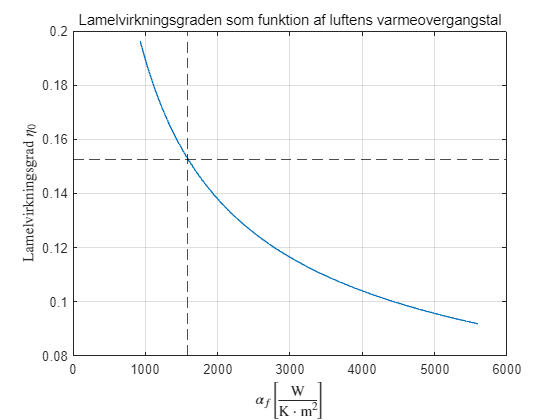

figure
plot(alpha_luft_num,eta_lamel_total)

yline(0.1527,"k--")
xline(1588.1,"k--")

grid("on")

title("Lamelvirkningsgraden som funktion af luftens varmeovergangstal","FontWeight","normal")
ylabel("Lamelvirkningsgrad $\eta_0$", "Interpreter","latex")
xlabel("$\alpha_f \left[\frac{\mathrm{W}}{\mathrm{K\cdot m^2}}\right]$", "Interpreter","latex")

exportgraphics(gcf, "Eta0Alphaf.png")

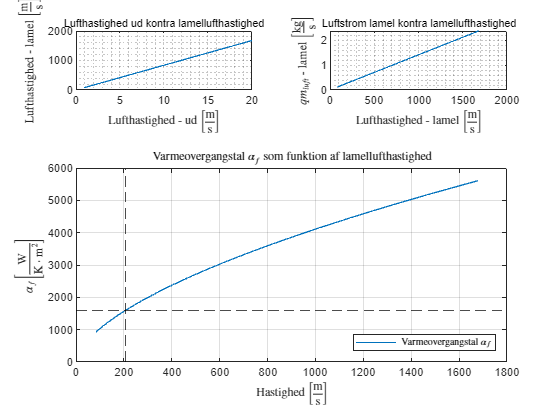

figure

tiledlayout(3,2)

nexttile
plot(V_3,c_2)
grid("minor")

title("Lufthastighed ud kontra lamellufthastighed","FontSize",8,"FontWeight","normal")
ylabel("Lufthastighed - lamel $\left[\frac{\mathrm{m}}{\mathrm{s}}\right]$", "Interpreter","latex")
xlabel("Lufthastighed - ud $\left[\frac{\mathrm{m}}{\mathrm{s}}\right]$", "Interpreter","latex")

nexttile
plot(c_2,qm_luft)
grid("minor")

title("Luftstrom lamel kontra lamellufthastighed","FontSize",8,"FontWeight","normal")
ylabel("$qm_{luft}$ - lamel $\left[\frac{\mathrm{kg}}{\mathrm{s}}\right]$", "Interpreter","latex")
xlabel("Lufthastighed - lamel $\left[\frac{\mathrm{m}}{\mathrm{s}}\right]$", "Interpreter","latex")


nexttile([2, 2])
plot(c_2, alpha_luft_num)
xline(205.11,"k--")
yline(1588.1,"k--")

grid("on")
title("Varmeovergangstal $\alpha_f$ som funktion af lamellufthastighed", "Interpreter","latex")
xlabel("Hastighed $\left[\frac{\mathrm{m}}{\mathrm{s}}\right]$", "Interpreter","latex")
ylabel("$\alpha_f \left[\frac{\mathrm{W}}{\mathrm{K\cdot m^2}}\right]$", "Interpreter","latex")
legend("Varmeovergangstal $\alpha_f$","Interpreter","latex","location","southeast")

exportgraphics(gcf, "varmeovergangstaljpg.jpg")

% Logaritmisk middel temperatur

t_fi = 82.253;    % Kølemiddel temp ind
t_fu = 30;    % Kølemiddel temp ud

t_lu = 27.32375;    % Luft temp ud
t_li = 22;    % Luft temp inid

T_LM = ((t_fi - t_lu)-(t_fu - t_li))/log((t_fi - t_lu)/(t_fu - t_li));
T_LM = vpa(T_LM, 4)

$$T\_LM = 24.36$$

% Modstande

R_i = 0.00391

R_i =                    0.00391



% Varmeledningsmodstand i rørene
lambda_kobber = 372% * u.W/(u.m*u.K);

lambda_kobber =    372


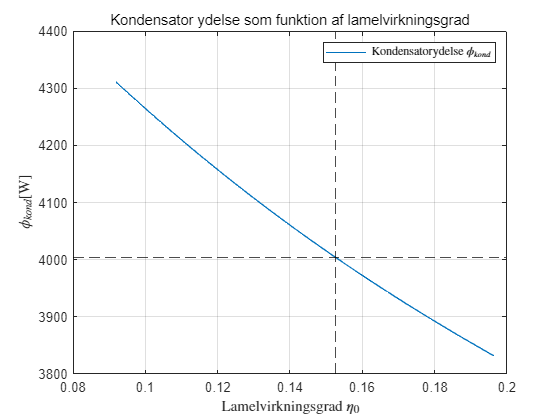


R_b = log(separateUnits(unitConvert(D_u,"SI"))/separateUnits(unitConvert(D_i,"SI")))/(2*pi*separateUnits(unitConvert(D,"SI"))*lambda_kobber);

% Modstand for lamellerne og hele luftsiden

R_f = 1./(alpha_luft_num .* separateUnits(A_t) .* eta_lamel_total);


% Total modstand
R_tot = R_i + R_b + R_f;


% Vekslerens varmeydelse

Phi_veksler = T_LM./R_tot;
Phi_veksler = vpa(unitConvert(Phi_veksler, u.W), 10);


figure
plot(eta_lamel_total, Phi_veksler)
yline(4003.35,"k--")
xline(0.1527,"k--")

grid("on")
title("Kondensator ydelse som funktion af lamelvirkningsgrad", "FontWeight","normal")
xlabel("Lamelvirkningsgrad $\eta_0$", "Interpreter","latex")
ylabel("$\phi_{kond} [\mathrm{W}]$", "Interpreter","latex")
legend("Kondensatorydelse $\phi_{kond}$","Interpreter","latex","location","northeast")

exportgraphics(gcf, "EtaPhi.png")

# Tluftud plot

% Logaritmisk middel temperatur

t_fi = 82.253;    % Kølemiddel temp ind
t_fu = 30;    % Kølemiddel temp ud

syms Tluftud
t_lu = Tluftud;    % Luft temp ud
t_li = 22;    % Luft temp inid

T_LM = ((t_fi - t_lu)-(t_fu - t_li))/log((t_fi - t_lu)/(t_fu - t_li));
T_LM = vpa(T_LM, 4);

cp_r134_ind = vpa(CP.PropsSI("C","T",273.15 + 82.253,"P",8.868*1e5,"R134a"),3)

$$cp\_r134\_ind = 1020.0$$

cp_luft = vpa(CP.PropsSI("C","T",273.15 + tfilm,"P",101325,"air"),4)

$$cp\_luft = 1008.0$$


qmr = 0.008497;
%qm_luft = 0.29;
h_ud = 241463;
h_ind = 467171;
%%


tluft_ud = zeros(1, length(R_tot));


for h = 1:length(R_tot)
phi_ydelse = vpa(separateUnits(T_LM)/R_tot(h),3);
phi_luft = vpa(separateUnits(qm_luft(h))*cp_luft*(t_lu - t_li),3);
phi_fluid = vpa(separateUnits(qmr)*cp_r134_ind*(t_fu - t_fi),3);
phi_v = vpa(separateUnits(qmr)*(h_ud - h_ind),3);

eq = phi_ydelse == phi_luft - phi_fluid - phi_v;

tluft_ud(h) = solve(eq, Tluftud);


end


phivek = subs(phi_ydelse, Tluftud, tluft_ud);
min(phivek)

$$ans = 4054.0869630112504727203729994496$$

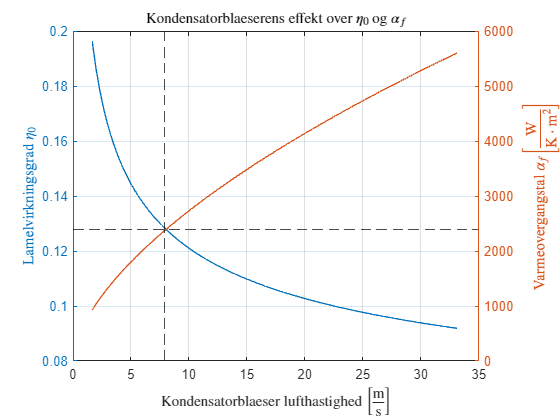


figure
grid("on")
title("Kondensatorblaeserens effekt over $\eta_0$ og $\alpha_f$", "Interpreter","latex")
yyaxis left
plot(c_1, eta_lamel_total)




ylabel("Lamelvirkningsgrad $\eta_0$","Interpreter","latex")



yyaxis right
plot(c_1, alpha_luft_num)

xline(7.9, "k--")
yline(0.128, "k--")

ylabel("Varmeovergangstal $\alpha_f \left[\frac{\mathrm{W}}{\mathrm{K\cdot m^2}}\right]$", "Interpreter","latex")
xlabel("Kondensatorblaeser lufthastighed  $\left[\frac{\mathrm{m}}{\mathrm{s}}\right]$","Interpreter","latex")

exportgraphics(gcf, "KondBlæsEtaAlpha.png")

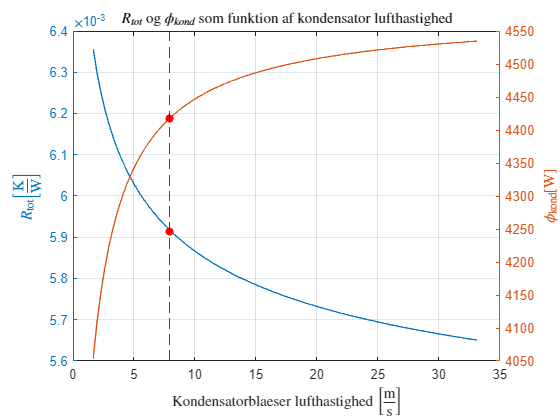



figure

title("$R_{tot}$ og $\phi_{kond}$ som funktion af kondensator lufthastighed","Interpreter","latex")
grid("on")
yyaxis left
plot(c_1, R_tot)
hold on
scatter(7.9, 5.915*1e-3, "r","filled")
hold off
ylabel("$R_{\mathrm{tot}} \left[\frac{\mathrm{K}}{\mathrm{W}}\right]$", "Interpreter","latex")

% xline(225, "k--")
% yline(1690, "k--")

yyaxis right
plot(c_1, phivek)
hold on
scatter(7.9, 4417, "r","filled")
hold off



ylabel("$\phi_{\mathrm{kond}} [\mathrm{W}]$", "Interpreter","latex")

xlabel("Kondensatorblaeser lufthastighed  $\left[\frac{\mathrm{m}}{\mathrm{s}}\right]$","Interpreter","latex")

xline(7.9, "k--")
exportgraphics(gcf, "KondBlæsRtotPhikond.png")